# Data exploration 📊🚀🤓

Code related to Figure 7, panels A-G & J from Marshall-Burghardt, et.al., 2024, Science Advances

Written by Rodrigo Migueles Ramirez. McGill University, Montreal, Canada, 2024.

## Guidelines

Before runing this script, the Setup, Preprocessing, Objects Properties and Exclusion Criteria scripts must have already be run. This should have generated big tables inside Options.Objects and in the Objects folder for each dataset.

The first step is to load the Objects data and filter it based on the selected criteria. Then, to generate each figure panel go to the indicated section and run it.

## Select which data you want to explore and load it

ExpID = [230601, 230606, 230609, 230621, 230710, 230712];
 
objectsTable = table();
allData = cell(length(ExpID));
% sourceFolder = 'Z:\Rodrigo\';
sourceFolder = 'MainFigures\Fig7\Fig 7 A-E\Raw Data\';
for id = 1:length(ExpID)
    % rootPath = uigetdir('H:\');
    load([sourceFolder, num2str(ExpID(id)), filesep, 'Objects', filesep, num2str(ExpID(id)), '-01-Objects.mat'], 'Objects');
    load([sourceFolder, num2str(ExpID(id)), filesep, num2str(ExpID(id)), '-Options.mat'], 'Options');
    load([sourceFolder, num2str(ExpID(id)), filesep, 'Metadata', filesep, num2str(ExpID(id)), '-Metadata.mat'], 'metadata');
    load([sourceFolder, num2str(ExpID(id)), filesep, num2str(ExpID(id)), '-ExpSettings.mat'], 'ExpSettings');
    retainedTable = struct2table(Options.Objects);
    currentTable = struct2table(Objects, 'RowNames', {Objects.FileKey});
    currentTable = cat(2, currentTable, retainedTable(:, "Retained"));
    allData{id} = currentTable;
    objectsTable = cat(1, objectsTable, currentTable);
end

Use this section to clear or re-start the analysis without having to wait for everything to be loaded again.

 
if length(ExpID) == 1
    objectsTable = table();
    retainedTable = struct2table(Options.Objects);
    currentTable = struct2table(Objects, 'RowNames', {Objects.FileKey});
    currentTable = cat(2, currentTable, retainedTable(:, "Retained"));
    objectsTable = cat(1, objectsTable, currentTable);
end

qualityFilter = "retained";
switch qualityFilter
    case "retained"        
        objectsTable = objectsTable(logical([objectsTable.Retained]), :);
    case "excluded"
        objectsTable = objectsTable(~logical([objectsTable.Retained]), :);
end

treatmentName = '';
if ~isempty(treatmentName)
    objectsTable = objectsTable(strcmpi(objectsTable.Treatment, treatmentName), :);
elseif strcmpi(qualityFilter, "all") && length(ExpID) == 1
    objectsTable = table();    
    retainedTable = struct2table(Options.Objects);
    currentTable = struct2table(Objects, 'RowNames', {Objects.FileKey});
    currentTable = cat(2, currentTable, retainedTable(:, "Retained"));
    objectsTable = cat(1, objectsTable, currentTable);    
end

ℹ️ For panels F7 C, D & E, choose the appropriate property here.

propertyName = 'Area';

conditions = categories(categorical(cellstr(objectsTable.Treatment)));
sizes = zeros(length(conditions),1);
for i = 1:length(conditions)
    sizes(i) = height(objectsTable(strcmpi(objectsTable.Treatment, conditions{i,1}),:));
end
propertyTableSize = max(sizes, [], 1);

if strcmpi(propertyName, 'Area')
    scalingFactor = metadata.pix_size^2;
else
    scalingFactor = 1;  
end

selectedConditions = {'CNTRL', 'NCDZL', 'NOC31', 'NOCY2'}';%{'CNTRL', 'CPD31', 'ROCKi', 'CPDY2'}';
    % selectedConditions = {'CNTRL', 'NCDZL', 'NOC31', 'NOCY2','Y31NC'}';
if isempty(selectedConditions)
    selectedConditions = conditions;
end

if length(ExpID) == 1
    propertyTable = table();
    if isempty(propertyName)
        if isempty(treatmentName)
            propertyTable = objectsTable;
        else    
            for c = 1:length(conditions)
                propertyTable(1:sizes(c),conditions{c,1}) = objectsTable(strcmpi(objectsTable.Treatment, conditions{c,1}), :);
            end
            findingZeros = table2array(propertyTable); colnames = propertyTable.Properties.VariableNames;
            findingZeros(findingZeros == 0) = NaN;
            propertyTable = array2table(findingZeros); propertyTable.Properties.VariableNames = colnames;            
        end
    else
        warning off
        for c = 1:length(conditions)
            propertyTable(1:sizes(c),conditions{c,1}) = objectsTable(strcmpi(objectsTable.Treatment, conditions{c,1}), propertyName);
        end
        findingZeros = table2array(propertyTable); colnames = propertyTable.Properties.VariableNames;
        findingZeros(findingZeros == 0) = NaN;
        propertyTable = array2table(findingZeros); propertyTable.Properties.VariableNames = colnames;
        warning on
    end

    % for c = 1:length(selectedConditions)
    %     propertyCell{c, id} = table2array(propertyTable(1:sizes(c), selectedConditions{c,1})).*scalingFactor;
    %     fileKeyCell{c, id} = table2array(objectsTable(strcmpi(objectsTable.Treatment, selectedConditions{c,1}), 'FileKey'));
    % end
    % 
    % warning off
    % for c = 1:length(selectedConditions)
    %     prismTable(1:size(propertyCell{c,id}, 1), strcat(num2str(ExpID(id)), '-', selectedConditions{c})) = array2table(propertyCell{c,id});
    % end           
    % warning on
else
    propertyCell = {}; fileKeyCell = {};
    selectedDuration = '2H';
    prismTable = table();
    if ~exist('objectsTable', 'var')
        objectsTable = table();
        needToLoadFiles = 1;
    else
        needToLoadFiles = 0;
    end
    
    for id = 1:length(ExpID)
        if needToLoadFiles
            load([sourceFolder, num2str(ExpID(id)), filesep, 'Objects', filesep, num2str(ExpID(id)), '-01-Objects.mat'], 'Objects');
            load([sourceFolder, num2str(ExpID(id)), filesep, num2str(ExpID(id)), '-Options.mat'], 'Options');
            load([sourceFolder, num2str(ExpID(id)), filesep, 'Metadata', filesep, num2str(ExpID(id)), '-Metadata.mat'], 'metadata');
            load([sourceFolder, num2str(ExpID(id)), filesep, num2str(ExpID(id)), '-ExpSettings.mat'], 'ExpSettings');
            retainedTable = struct2table(Options.Objects);
            currentTable = struct2table(Objects, 'RowNames', {Objects.FileKey});
            objectsTable = cat(2, currentTable, retainedTable(:, "Retained"));
            % objectsTable = cat(1, objectsTable, currentTable);
        end
        
        switch qualityFilter
            case "retained"        
                objectsTable = objectsTable(logical([objectsTable.Retained]), :);
            case "excluded"
                objectsTable = objectsTable(~logical([objectsTable.Retained]), :);
        end

        objectsTable = objectsTable(strcmpi(objectsTable.Duration, selectedDuration), :);

        % conditions = categories(categorical(selectedConditions));
        % conditions = categories(categorical(cellstr(objectsTable.Treatment)));
        % selectedConditions = conditions;
        % conditions = selectedConditions;

        sizes = zeros(length(selectedConditions),1);
        for i = 1:length(selectedConditions)
            sizes(i) = height(objectsTable(strcmpi(objectsTable.Treatment, selectedConditions{i,1}),:));
        end        
        propertyTableSize = max(sizes, [], 1);

        if ~isempty(propertyName)
            propertyTable = table();
            warning off
            for c = 1:length(selectedConditions)
                propertyTable(1:sizes(c), selectedConditions{c,1}) = objectsTable(strcmpi(objectsTable.Treatment, selectedConditions{c,1}), propertyName);
            end
            findingZeros = table2array(propertyTable); colnames = propertyTable.Properties.VariableNames;
            findingZeros(findingZeros == 0) = NaN;
            propertyTable = array2table(findingZeros); propertyTable.Properties.VariableNames = colnames;
            warning on

            for c = 1:length(selectedConditions)
                propertyCell{c, id} = table2array(propertyTable(1:sizes(c), selectedConditions{c,1})).*scalingFactor;
                fileKeyCell{c, id} = table2array(objectsTable(strcmpi(objectsTable.Treatment, selectedConditions{c,1}), 'FileKey'));
            end
            % 
            % warning off
            % for c = 1:length(selectedConditions)
            %     prismTable(1:size(propertyCell{c,id}, 1), strcat(num2str(ExpID(id)), '-', selectedConditions{c})) = array2table(propertyCell{c,id});
            % end           
            % warning on
    
            % fig = figure;
            % vp = violinplot(propertyTable(:, selectedConditions));
            % for v = 1:size(vp,2)
            %     vp(1,v).ViolinPlot.PickableParts = 'none';
            %     vp(1,v).ScatterPlot.DataTipTemplate.DataTipRows(2).Label = propertyName;
            %     conditionName = xticklabels;
            %     row = dataTipTextRow("File Key", table2array(objectsTable(strcmpi(objectsTable.Treatment, conditionName{v,1}), "FileKey")));
            %     vp(1,v).ScatterPlot.DataTipTemplate.DataTipRows(end+1) = row;
            %     ylabel(propertyName);            
            % end
            % ax = gca;
            % title(ExpID(1, id))
            % fig.Color = 'w';
            % 
            % if strcmpi(selectedConditions{4,1} , 'CPDY2')
            %     condName = '-CPD31-Y27632';
            % elseif strcmpi(selectedConditions{end,1} , 'NOCY2')
            %     condName = '-NocSolo';
            % end
            % 
            % savefig(fig, ['C:\Users\malvi\McGill University\Seph Marshall-Burghardt - results good_Feb2023\Fig 7',...
            %     filesep, 'Violin-',  propertyName, condName, '-', num2str(ExpID(1,id)), '.fig']);
            % exportgraphics(fig, ['C:\Users\malvi\McGill University\Seph Marshall-Burghardt - results good_Feb2023\Fig 7',...
            %     filesep, 'Violin-',  propertyName, condName, '-', num2str(ExpID(1,id)), '.png']);
            % hold off;
        else
            if isempty(treatmentName)
                propertyTable = objectsTable;
                warning off
                for c = 1:length(selectedConditions)
                    propertyTable(1:sizes(c), selectedConditions{c,1}) = objectsTable(strcmpi(objectsTable.Treatment, selectedConditions{c,1}), :);
                end
                findingZeros = table2array(propertyTable); colnames = propertyTable.Properties.VariableNames;
                findingZeros(findingZeros == 0) = NaN;
                propertyTable = array2table(findingZeros); propertyTable.Properties.VariableNames = colnames;
                warning on
                for c = 1:length(selectedConditions)
                    propertyCell{c, id} = table2array(propertyTable(1:sizes(c), selectedConditions{c,1})).*scalingFactor;
                    fileKeyCell{c, id} = table2array(objectsTable(strcmpi(objectsTable.Treatment, selectedConditions{c,1}), 'FileKey'));
                end
            else    
                for c = 1:length(selectedConditions)
                    propertyTable(1:sizes(c),selectedConditions{c,1}) = objectsTable(strcmpi(objectsTable.Treatment, selectedConditions{c,1}), :);
                end
                findingZeros = table2array(propertyTable); colnames = propertyTable.Properties.VariableNames;
                findingZeros(findingZeros == 0) = NaN;
                propertyTable = array2table(findingZeros); propertyTable.Properties.VariableNames = colnames;            
            end           
        end
        disp(ExpID(1, id));
    end
end

      230601

      230606

      230609

      230621

      230710

      230712



Error using struct2table
The RowNames property must be a string array or a cell array, with each name containing one or more characters.


for t = 1:size(propertyCell,1) % Treatment
    for d = 1:size(propertyCell,2) % Day
        meansArray(t,d) = mean(propertyCell{t,d}, 'omitnan');
        mediansArray(t,d) = median(propertyCell{t,d}, 'omitnan');
    end
end

findingZeros = table2array(prismTable); colnames = prismTable.Properties.VariableNames;
findingZeros(findingZeros == 0) = NaN;
prismTable = array2table(findingZeros); prismTable.Properties.VariableNames = colnames;


Filter by treatment duration:

duration =  '';
if ~isempty(duration) && isempty(propertyName)
    propertyTable = propertyTable(strcmpi(propertyTable.Duration, duration),:);
else
end

## Scatter Plots

if isempty(propertyName)    
    selected_Y_axis = "Area"; selected_X_axis = "MeanIntensity";
    clear s;
    for p = 1:length(conditions)
        s(p) = scatter(table2array(propertyTable(strcmpi(propertyTable.Treatment, conditions{p,1}), selected_X_axis)),...
            table2array(propertyTable(strcmpi(propertyTable.Treatment, conditions{p,1}), selected_Y_axis)));
        s(p).MarkerFaceColor = s(p).MarkerEdgeColor;
        s(p).MarkerFaceAlpha = 0.3;
        s(p).DataTipTemplate.DataTipRows(1).Label = selected_X_axis;
        s(p).DataTipTemplate.DataTipRows(2).Label = selected_Y_axis;
        row = dataTipTextRow("File Key", table2array(propertyTable(strcmpi(propertyTable.Treatment, conditions{p,1}),"FileKey")));
        s(p).DataTipTemplate.DataTipRows(end+1) = row;
        hold on
    end
    

Show sets:

    switch length(conditions)
        case 4
            s(1).Visible = true;
            s(2).Visible = true;
            s(3).Visible = true;
            s(4).Visible = true;

            legend({'Control', 'CPD31', 'ROCKi', 'CPD31 + ROCKi'}, "Location","best");            
        case 5            
            s(1).Visible = true;
            s(2).Visible = true;
            s(3).Visible = true;
            s(4).Visible = true;
            s(5).Visible = true;
            legend({'Control', 'CPD31', 'CPD31 + ROCKi', 'Nocodazole','ROCKi'},"Location","best");

        case 7
            s(1).Visible = true;
            s(2).Visible = true;
            s(3).Visible = true;
            s(4).Visible = true;
            s(5).Visible = true;
            s(6).Visible = true;
            s(7).Visible = true;            
            legend({'Control', 'CPD31', 'CPD31 + ROCKi', 'Nocodazole', 'Nocodazole + CPD31', 'Nocodazole + ROCKi', 'ROCKi'},"Location","best");

        case 8
            s(1).Visible = false;
            s(2).Visible = false;
            s(3).Visible = true;
            s(4).Visible = true;
            s(5).Visible = false;
            s(6).Visible = false;
            s(7).Visible = false;
            s(8).Visible = false;
            legend({'Control', 'CPD31', 'CPD31 + ROCKi', 'Nocodazole', 'Nocodazole + CPD31', 'Nocodazole + ROCKi', 'ROCKi', 'ROCKi + CPD31 + Nocodazole'},"Location","best");
    end
    
    xlabel(selected_X_axis);
    ylabel(selected_Y_axis);
    title(num2str(ExpID));
    title('All Trials');
    if strcmpi(selected_X_axis, 'Solidity') || strcmpi(selected_X_axis, 'Eccentricity')    
        xlim([0,1]);
    end
    if strcmpi(selected_Y_axis, 'Solidity') || strcmpi(selected_Y_axis, 'Eccentricity')
        ylim([0,1]);
    end
    
    fig = gcf; fig.Color = 'k';
    ax = gca; ax.Color = 'k'
    hold off
end

## Inspect selected objects

This section helps ensure the exclusion criteria was sufficiently thorough to discard artifacts. Select filtering criteria, sorting direction, and list size to show, for example, the biggest 15 cells across all treatments. Then run the next block to launch an interactive inspection routine. During the inspection, the user can choose to retain or discard an inspected cell. 

If there are modifications to the retained / discarded status, the plots need to be updated. To do this, go back to the section Reset Objects Table and run all relevant blocks after that.

propertyName = 'Area';
treatmentName = '';
direction = 'descend';
topSize = 15;

propertyTable = objectsTable;
propertyTable = sortrows(propertyTable, propertyName, direction);
if ~isempty(treatmentName)
    propertyTable = propertyTable(strcmpi(propertyTable.Treatment, treatmentName), :);
end
propertyTable = propertyTable(1:topSize,:);
selectedObjectsList = table2struct(propertyTable);

 
Options = inspectObjects(selectedObjectsList, Options, ExpSettings, metadata);
save([ExpSettings.CloudPath, ExpSettings.ExpID, '-Options.mat'], 'Options', '-v7.3');

## Violin Plots 

For plotting a given property, across conditions, for one single dataset. For plotting multiple datasets at the same time, see Super Violin Plots

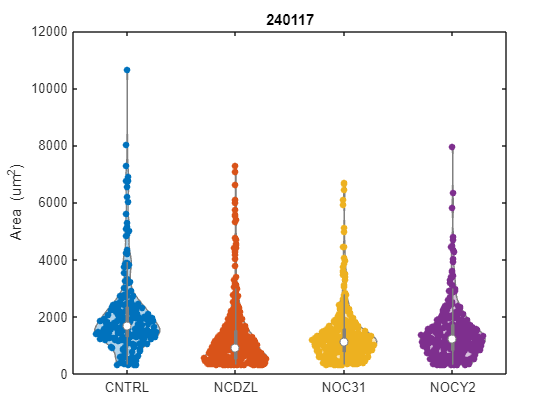

if ~isempty(propertyName)
    if length(ExpID) > 1 % Super violin plots
        fig = figure;
        vp = violinplot(propertyCell);
    else % Violin plots
        fig = figure;
        vp = violinplot(propertyTable(:, selectedConditions).*scalingFactor);
        for v = 1:size(vp,2)
            vp(1,v).ViolinPlot.PickableParts = 'none';
            vp(1,v).ScatterPlot.DataTipTemplate.DataTipRows(2).Label = propertyName;
            conditionName = xticklabels;
            row = dataTipTextRow("File Key", table2array(objectsTable(strcmpi(objectsTable.Treatment, conditionName{v,1}), "FileKey")));
            vp(1,v).ScatterPlot.DataTipTemplate.DataTipRows(end+1) = row;
        end
        ylabel(propertyName);
        if strcmpi(propertyName, 'Area'); ylabel([propertyName, ' (um^{2})']); end
        ax = gca;
        fig.Color = 'w';
    end
else
    disp('Please select only one property');
end
title(ExpID);
hold off

% ax.YScale = 'log';

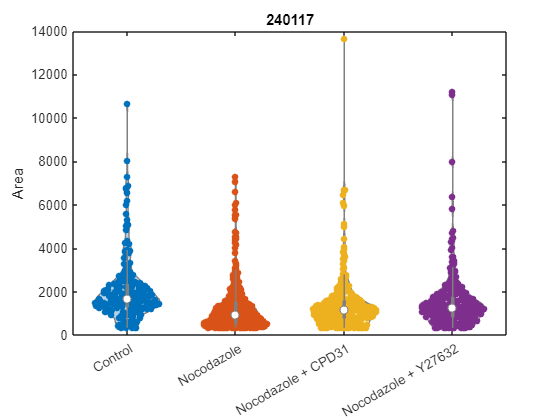

if ~isempty(propertyName)
    if length(ExpID) >1 % Super violin plots

    else % Violin plots
        fig = figure;
        vp = violinplot(propertyTable(:, selectedConditions).*scalingFactor);
        for v = 1:size(vp,2)
            % vp(1,v).ViolinPlot.Visible = 0;
            vp(1,v).ScatterPlot.DataTipTemplate.DataTipRows(2).Label = propertyName;
            conditionName = xticklabels;
            row = dataTipTextRow("File Key", table2array(objectsTable(strcmpi(objectsTable.Treatment, conditionName{v,1}), "FileKey")));
            vp(1,v).ScatterPlot.DataTipTemplate.DataTipRows(end+1) = row;
            ylabel(propertyName);            
        end
        ax = gca;
    end
else
    disp('Please select only one property');
end
ax.XTickLabel{1,1} = 'Control';
ax.XTickLabel{2,1} = 'Nocodazole';
ax.XTickLabel{3,1} = 'Nocodazole + CPD31';
ax.XTickLabel{4,1} = 'Nocodazole + Y27632';
ax.XTickLabel{5,1} = 'Nocodazole + CPD31 + Y27632';
title(ExpID);
hold off

## Super Violin Plot

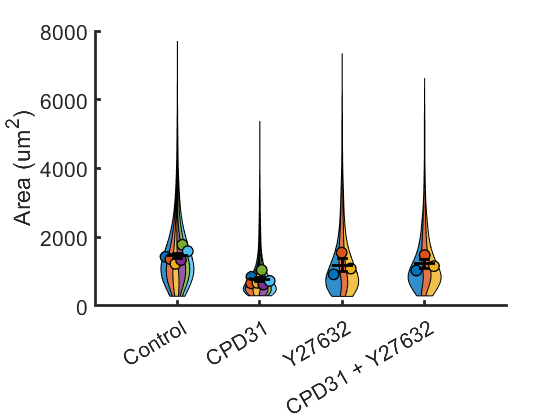

svf = figure;
sva = gca; hold(sva, 'on');
cmap = lines(size(propertyCell, 2));
for c = 1:length(selectedConditions)
    nonEmptyArray = ones(size(propertyCell));
    for t = 1:size(propertyCell, 2)
        if isempty(propertyCell{c,t}); nonEmptyArray(c,t) = 0; end
    end

    svp = superviolin(propertyCell(c, [find(nonEmptyArray(c,:))]), 'Xposition', c, 'Width', 0.4, 'LUT', 'lines');
%     for i = 1:size(svp, 2)-1
%         colorIndex = [find(nonEmptyArray(c,:))];
%         colorIndex = colorIndex + 3;
%         thisPatch = svp(1,i);        
%         thisPatch.FaceColor = cmap(colorIndex(i), :);
%         thisDot = sva.Children;
%     end
end
sva.XTick = 1:length(selectedConditions);
sva.XTickLabel = {'Control'; 'CPD31'; 'Y27632'; 'CPD31 + Y27632'};
% sva.XTickLabel = {'Control'; 'Nocodazole'; 'Nocodazole + CPD31'; 'Nocodazole + Y27632'};
% sva.XTickLabel = {'Control'; 'Nocodazole'; 'Nocodazole + CPD31'; 'Nocodazole + Y27632'; 'Nocodazole + CPD31 + Y27632'};
% lg = legend({'June 1st', 'June 6th', 'June 9th', 'June 21st', 'July 10th', 'July 12th'}, 'Location','bestoutside');
for t = 1:size(propertyCell, 2)
    trialN = 0;
    for cd = 1:size(propertyCell, 1)
        trialN = trialN + size(propertyCell{cd,t}, 1);
    end
    labels{1, t} = ['Trial ', num2str(t), ' (', num2str(trialN), ' cells)'];       
end
% lg = legend(labels, 'Location','bestoutside');

for cd = 1:size(propertyCell, 1)
    conditionN = 0;
    for t = 1:size(propertyCell, 2)
        conditionN = conditionN + size(propertyCell{cd,t}, 1);
    end
%     sva.XTickLabel{cd,1} = [sva.XTickLabel{cd,1}, ' (', num2str(conditionN), ' cells)'];    
end

if strcmpi(propertyName, 'Area')
%     sva.YLim(2) = 3000*scalingFactor;
    sva.YLabel.String = [propertyName, ' (um^{2})'];
    sva.YTickLabel;
    % sva.YScale = 'log';
elseif strcmpi(propertyName, 'Solidity') || strcmpi(propertyName, 'Eccentricity')
    sva.YLim = [0,1];
    sva.YLabel.String = propertyName;
else
    sva.YLabel.String = propertyName;
end
sva.LineWidth = 2;
sva.FontSize = 16;
drawnow;
hold off

% sva.FontSize = 16; 

## F7C-E: Summary Violin Plots

Select to show Means or Medians:

statisticMetric = 'Mean';
switch statisticMetric
    case 'Mean'
        summaryData = meansArray;
    case 'Median'
        summaryData = mediansArray;
end

Remove Trials that do not have all the conditions:

if any(isnan(summaryData),"all")
    [~,col] = find(isnan(summaryData));
    summaryData = summaryData(:,setdiff(1:size(summaryData,2), unique(col)));
end

Convert to a table for violin plot function:

summaryTable = array2table(summaryData',"VariableNames", selectedConditions);

Plot Violins:

fig = figure;
vpa = gca;
vpSummary = violinplot(summaryTable);

Fetch patch, scatter and line objects:

g = 1; p = 1; l = 1;
for c = 1:size(vpa.Children, 1)
    if strcmpi(vpa.Children(c).Type, 'Patch')
        patchObjects{p} = vpa.Children(c);
        p = p + 1;
    elseif strcmpi(vpa.Children(c).Type, 'Scatter')
        scatterGroup{g} = vpa.Children(c);
        g = g + 1;
    elseif strcmpi(vpa.Children(c).Type, 'Line')
        linesGroup{l} = vpa.Children(c);
        linesGroup{l}.Visible = 'on';
        l = l + 1;
    end
end

Color and label patches:

Tags = selectedConditions;%{'Mix', 'Y27632', 'CPD31', 'Control'}; 
if strcmpi(selectedConditions{2}, 'NCDZL')    
    Colors = {[0.49,0.18,0.56], [0.85,0.33,0.10], [0.39,0.83,0.07], [0.00,0.45,0.74]}; % Blue Green Orange Purple (in reverse order)
else
    Colors = {[0.64,0.08,0.18], [0.49,0.18,0.56], [0.85,0.33,0.10],[0.00,0.45,0.74]}; % Blue Orange Purple Burgundy (in reverse order)
end
t = 1;
for p = 2:2:8
    patchObjects{p}.Tag = ['Patch', Tags{t}]; 
    patchObjects{p}.FaceColor = Colors{t};
    patchObjects{p}.EdgeColor = patchObjects{p}.FaceColor;
    patchObjects{p}.FaceAlpha = 0.5;
    patchObjects{p}.LineWidth = 1;
    
    % Match the color of the mean line and hide it:
    linesGroup{p}.Color = Colors{t};
    linesGroup{p}.Visible = 0;
    
    t = t + 1;
end

Hide whiskers and error bar patches

for p = 1:2:7
    patchObjects{p}.EdgeColor = 'k';
    patchObjects{p}.FaceColor = 'k';
    patchObjects{p}.Visible = 'off';    
    
    linesGroup{p}.Visible = 'off'; % Hide whiskers
end

Color scatterplots:

c = 1;
for g = 4:4:16
    scatterGroup{g}.MarkerFaceColor = Colors{c};
    scatterGroup{g}.MarkerEdgeColor = 'k';
    scatterGroup{g}.LineWidth = 1;
    scatterGroup{g}.SizeData = 36;
    c = c + 1;       
end

c = 1;
for g = 3:4:15
    scatterGroup{g}.MarkerFaceColor = Colors{c};
    scatterGroup{g}.MarkerEdgeColor = 'k';
    scatterGroup{g}.LineWidth = 1.5;
    scatterGroup{g}.SizeData = 46;
    scatterGroup{g}.Visible = 'off';
    c = c + 1;          
end


Add trial connection dashed lines:

for g = 4:-1:2
    for i = 1:size(summaryData, 2)
        line([scatterGroup{g*4}.XData(i), scatterGroup{g*4-4}.XData(i)],...
            [scatterGroup{g*4}.YData(i), scatterGroup{g*4-4}.YData(i)], 'LineStyle', ':', 'Color', 'k', 'Parent', vpa);        
    end
end

%% Disable violin patches pickable parts to be able to pick on the scatters:
% for p = 1:size(patchObjects,2)
%     patchObjects{p}.PickableParts = 'none';    
% end

Add standard deviation error bars and means:

for c = 1:4
    line([c,c], [mean(summaryData(c,:))+std(summaryData(c,:)),...
        mean(summaryData(c,:))-std(summaryData(c,:))], 'LineWidth', 2, 'Color', 'k', 'Parent', vpa);
    scatter(c, mean(summaryData(c,:)), 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'SizeData', 46, 'Parent', vpa);
end

Add labels and adjust axes properties:

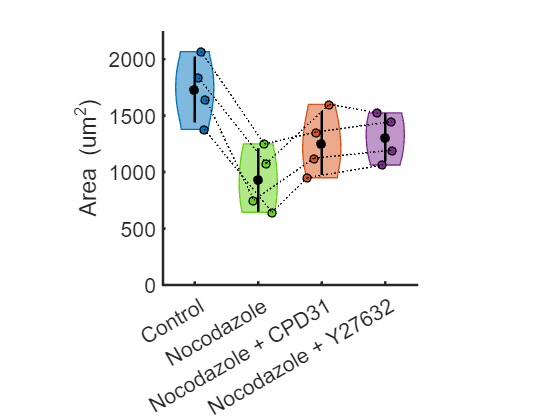

if strcmpi(selectedConditions{2}, 'NCDZL')
    xticklabels({'Control', 'Nocodazole', 'Nocodazole + CPD31', 'Nocodazole + Y27632'});
else
    xticklabels({'Control', 'CPD31', 'Y27632', 'CPD31 + Y27632'});
end

vpa.Box = 'off';
vpa.FontSize = 16;
vpa.XLim = [0.5,4.5];
if strcmpi(propertyName, 'Area')
%     vpa.YLim(1) = 3000*scalingFactor;
    vpa.YLim(1) = 0;
    vpa.YLim(2) = 2250;
%     if strcmpi(selectedConditions{2}, 'NCDZL'); vpa.YLim(2) = vpa.YLim(2) - 500; end
    vpa.XLim = [0.5,4.5];
    vpa.YLabel.String = [propertyName, ' (um^{2})'];
    % sva.YScale = 'log';
elseif strcmpi(propertyName, 'Solidity') || strcmpi(propertyName, 'Eccentricity')
    vpa.YLim = [0,1];
    vpa.YLabel.String = propertyName;    
else
    vpa.YLabel.String = propertyName;
end
vpa.LineWidth = 2;
axis(vpa, 'square');




% title([statisticMetric, 's of the ', propertyName, ' of all datasets.']);

## F7B: Show selected cells to illustrate solidity and eccentricity

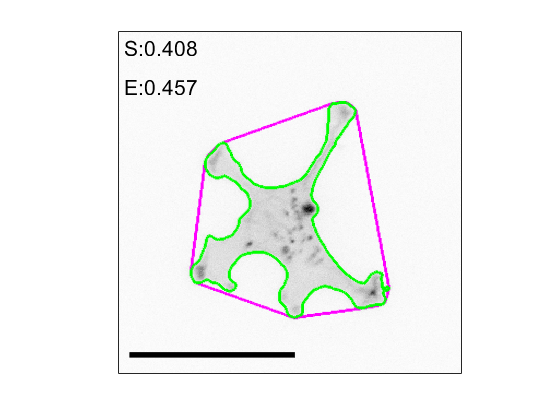

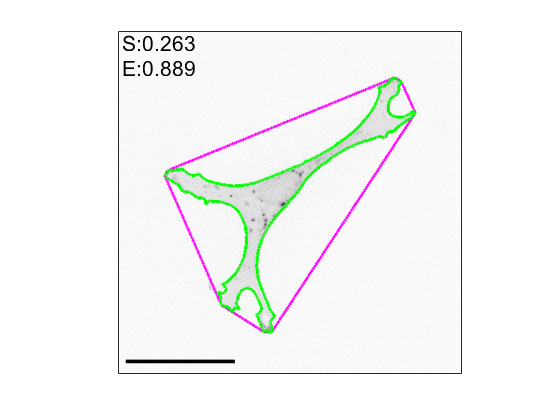

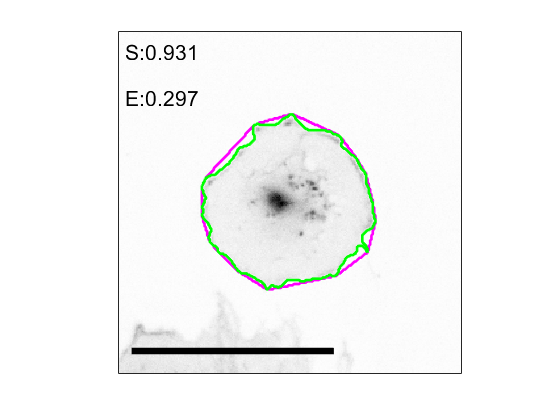

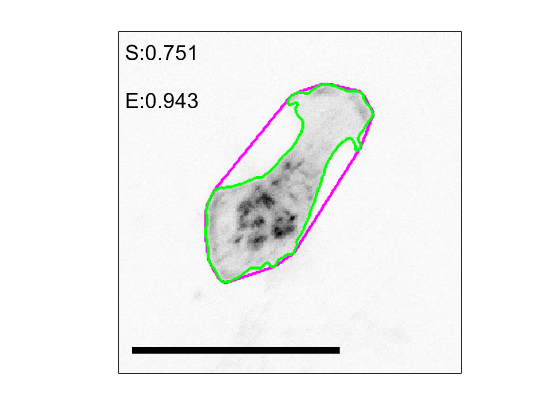

selectedCells = struct();
selectedCells(1).FileKey = '230601-01-099-01-C2-CPD31-1H';
selectedCells(2).FileKey = '230601-01-347-08-E5-CPDY2-2H';
selectedCells(3).FileKey = '230621-01-007-04-B10-CNTRL-2H';
% selectedCells(4).FileKey = '230710-01-007-01-B2-CNTRL-2H';
selectedCells(4).FileKey = '230621-01-008-07-B10-CNTRL-2H';

if ~exist('maxSize', 'var'); maxSize = 1; end
for f = 1:4
    fileKey = selectedCells(f).FileKey;
    TrialDate = fileKey(1:6);
    load([sourceFolder, TrialDate, filesep, 'Metadata', filesep, TrialDate, '-Metadata.mat']);
    file = fileKey(8:9); file = str2num(file);
    site = fileKey(11:13); site = str2num(site);
    crop = fileKey(15:16); crop = str2num(crop);
    well = getWellIndex(file, site, metadata);
    fileKey = getFileKey(file, site, 1, metadata, "R", well, crop);
    load([sourceFolder, TrialDate, filesep, TrialDate, '-ExpSettings.mat'], 'ExpSettings');    
    img = readFileToStack([ExpSettings.CroppedPath, fileKey, '.tif']);
    solidity = table2array(objectsTable(fileKey, 'Solidity'));
    eccentricity = table2array(objectsTable(fileKey, 'Eccentricity'));
    majorAxis = table2array(objectsTable(fileKey, 'MajorAxis'));
    minorAxis = table2array(objectsTable(fileKey, 'MinorAxis'));
    orientationAngle = table2array(objectsTable(fileKey, 'Orientation'));
    fileKey = getFileKey(file, site, 0, metadata, "R", well, crop);
    load([sourceFolder, TrialDate, filesep, 'Masks', filesep, fileKey, '-Mask.mat'], 'mask');    
    
    fig = figure;

    img = makeSquare(imcomplement(img));
    imagesc(img); colormap('gray');    
    axis image; 
    maxSize = max(maxSize, max(size(img,1), size(img,2)));
    xl = xlim; yl = ylim;
%     xl(1) = xl(1) - (maxSize/2 - size(img,2)/2);
%     xl(2) = xl(2) + (maxSize/2 - size(img,2)/2);
%     yl(1) = yl(1) - (maxSize/2 - size(img,1)/2);
%     yl(2) = yl(2) + (maxSize/2 - size(img,1)/2);    
    ax = gca;
    ax.XLim = xl; ax.YLim = yl;

    hold on;
    sText = text(xl(1) + 5, yl(1) + 15, ['S:', num2str(round(solidity,3))], 'Color', 'k', 'FontSize', 16);
    eText = text(xl(1) + 5, yl(1) + 50, ['E:', num2str(round(eccentricity,3))], 'Color', 'k', 'FontSize', 16);
    
    cHull = bwconvhull(makeSquare(mask));
    cOutline = bwboundaries(cHull); cOutline = cOutline{1,1};
    plot(cOutline(:,2), cOutline(:,1), 'm', 'LineWidth', 2);
    
%     ellipse = rectangle('Position',[0, 0, majorAxis, minorAxis], 'Curvature', 1, '', );
    
    outline = bwboundaries(makeSquare(mask)); outline = outline{1,1};
    plot(outline(:,2), outline(:,1), 'g', 'LineWidth', 2);
    
    xticks([]); yticks([]);
    
    scaleBar = rectangle('Position', ...
        [xl(1) + 10, yl(2) - 20,...
        50/metadata(file).pix_size, 5], 'FaceColor', 'k', 'EdgeColor', 'none');
    
    savefig(fig, ['D:\McGill University\Seph Marshall-Burghardt - results good_Feb2023\Fig 7\',...
        'ExampleCells-', selectedCells(f).FileKey, '.fig']);
    saveas(fig, ['D:\McGill University\Seph Marshall-Burghardt - results good_Feb2023\Fig 7\',...
        'ExampleCells-', selectedCells(f).FileKey, '.svg']);
    exportgraphics(fig, ['D:\McGill University\Seph Marshall-Burghardt - results good_Feb2023\Fig 7\',...
        'ExampleCells-', selectedCells(f).FileKey, '.png']);    
end

## F7A: Show representative cells of each condition

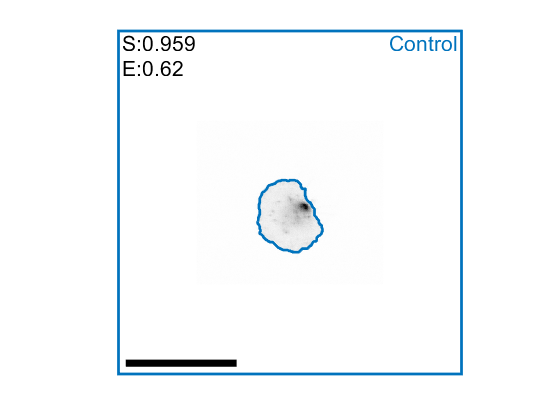

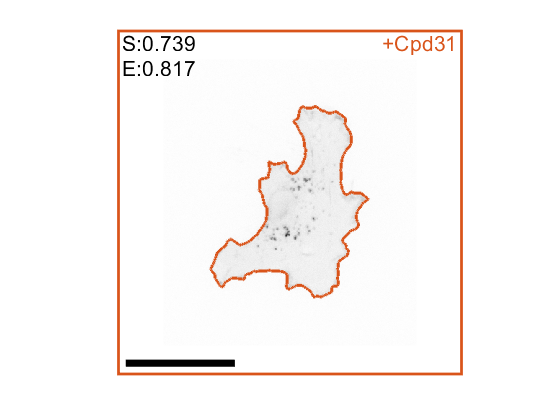

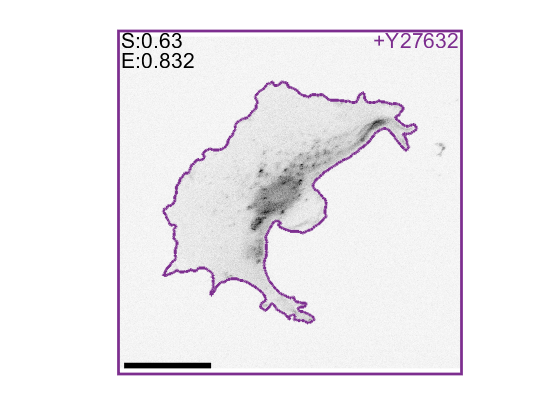

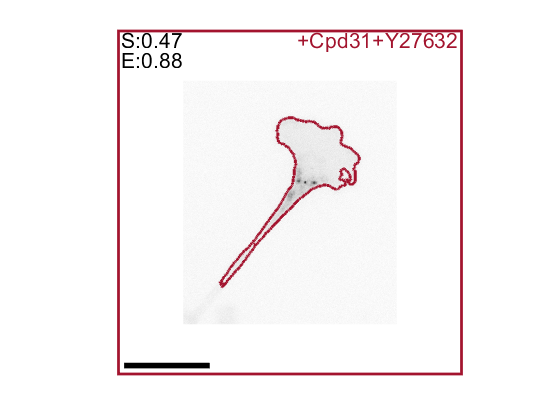

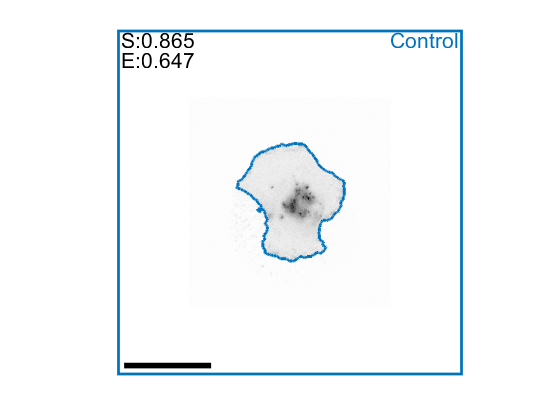

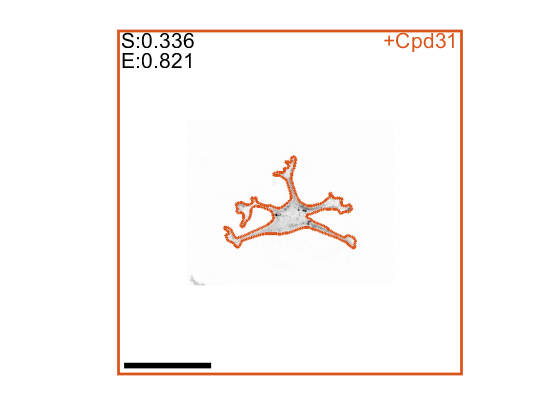

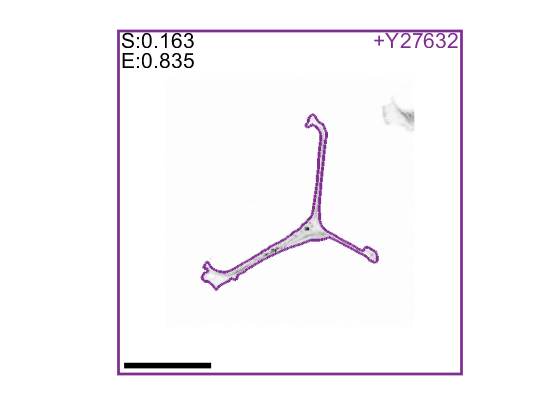

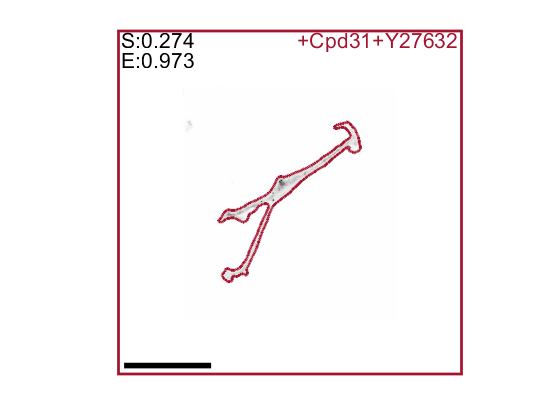

representativeCells = struct();
representativeCells(1).FileKey = '230712-01-050-09-C2-CNTRL-2H'; % Av Control
% representativeCells(2).FileKey = '230710-01-086-08-C3-CPD31-2H';
% representativeCells(2).FileKey = '230609-01-144-04-C4-CPD31-2H';
% representativeCells(2).FileKey = '230606-01-204-05-C6-CPD31-2H';
representativeCells(2).FileKey = '230601-01-150-05-C5-CPD31-2H';% Av CPD31
% representativeCells(3).FileKey = '230601-01-231-02-D4-ROCKi-2H';
representativeCells(3).FileKey = '230710-01-143-12-D2-ROCKi-2H';% Av Y2
representativeCells(4).FileKey = '230609-01-328-09-E4-CPDY2-2H';% Av CY

representativeCells(5).FileKey = '230712-01-052-03-C2-CNTRL-2H';%Ex Ctrl
representativeCells(6).FileKey = '230621-01-036-04-C10-CPD31-2H';% Ex CPD31
representativeCells(7).FileKey = '230621-01-082-03-D11-ROCKi-2H';% Ex Y2
representativeCells(8).FileKey = '230621-01-113-05-E11-CPDY2-2H';% Ex CY

% Colors = {[0.64,0.08,0.18], [0.49,0.18,0.56], [0.85,0.33,0.10], [0.00,0.45,0.74]}; % Blue Orange Purple Burgundy (in reverse order)
Colors = {[0.00,0.45,0.74], [0.85,0.33,0.10], [0.49,0.18,0.56], [0.64,0.08,0.18],...
    [0.00,0.45,0.74], [0.85,0.33,0.10], [0.49,0.18,0.56], [0.64,0.08,0.18]}; % Blue Orange Purple Burgundy (twice)
Tags = {'Control', '+Cpd31', '+Y27632', '+Cpd31+Y27632', 'Control', '+Cpd31', '+Y27632', '+Cpd31+Y27632'};

if ~exist('maxSize', 'var'); maxSize = 1; end
for f = 1:8
    fileKey = representativeCells(f).FileKey;
    TrialDate = fileKey(1:6);
    load([sourceFolder, TrialDate, filesep, 'Metadata', filesep, TrialDate, '-Metadata.mat']);
    file = fileKey(8:9); file = str2num(file);
    site = fileKey(11:13); site = str2num(site);
    crop = fileKey(15:16); crop = str2num(crop);
    well = getWellIndex(file, site, metadata);
    fileKey = getFileKey(file, site, 1, metadata, "R", well, crop);
    load([sourceFolder, TrialDate, filesep, TrialDate, '-ExpSettings.mat'], 'ExpSettings');    
    img = readFileToStack([ExpSettings.CroppedPath, fileKey, '.tif']);
    solidity = table2array(objectsTable(fileKey, 'Solidity'));
    eccentricity = table2array(objectsTable(fileKey, 'Eccentricity'));
    fileKey = getFileKey(file, site, 0, metadata, "R", well, crop);
    load([sourceFolder, TrialDate, filesep, 'Masks', filesep, fileKey, '-Mask.mat'], 'mask');    
    fig = figure;
    
    img = imcomplement(img);
    imagesc(img); colormap('gray');    
    axis image; 
    maxSize = max(maxSize, max(size(img,1), size(img,2)));
    xl = xlim; yl = ylim;
    xl(1) = xl(1) - (maxSize/2 - size(img,2)/2);
    xl(2) = xl(2) + (maxSize/2 - size(img,2)/2);
    yl(1) = yl(1) - (maxSize/2 - size(img,1)/2);
    yl(2) = yl(2) + (maxSize/2 - size(img,1)/2);    
    ax = gca;
    ax.XLim = xl; ax.YLim = yl;
    
    hold on;
    sText = text(xl(1) + 5, yl(1) + 15, ['S:', num2str(round(solidity,3))], 'Color', 'k', 'FontSize', 16);
    eText = text(xl(1) + 5, yl(1) + 50, ['E:', num2str(round(eccentricity,3))], 'Color', 'k', 'FontSize', 16);
     
%     cHull = bwconvhull(makeSquare(mask));
%     cOutline = bwboundaries(cHull); cOutline = cOutline{1,1};
%     plot(cOutline(:,2), cOutline(:,1), 'm', 'LineWidth', 2);
    
    outline = bwboundaries(mask); outline = outline{1,1};
    plot(outline(:,2), outline(:,1), 'Color',  Colors{f}, 'LineWidth', 2);
    
    frameOutline = rectangle('Position', [xl(1), yl(1), xl(2)-xl(1), yl(2)-yl(1)],...
        'FaceColor', 'none', 'EdgeColor', Colors{f}, 'LineWidth', 2);
    labelTag = text(xl(2)-5, yl(1) + 15, Tags{f}, 'HorizontalAlignment', 'Right', 'Color', Colors{f}, 'FontSize', 16);
    
    xticks([]); yticks([]);
    
    scaleBar = rectangle('Position', ...
        [xl(1) + 10, yl(2) - 20,...
        50/metadata(file).pix_size, 10], 'FaceColor', 'k', 'EdgeColor', 'none');
    ax.Box = 0;
    axis off;
    
    savefig(fig, ['D:\McGill University\Seph Marshall-Burghardt - results good_Feb2023\Fig 7\',...
        'RepresentativeCells-', representativeCells(f).FileKey, '.fig']);
    saveas(fig, ['D:\McGill University\Seph Marshall-Burghardt - results good_Feb2023\Fig 7\',...
        'RepresentativeCells-', representativeCells(f).FileKey, '.svg']);
    exportgraphics(fig, ['D:\McGill University\Seph Marshall-Burghardt - results good_Feb2023\Fig 7\',...
        'RepresentativeCells-', representativeCells(f).FileKey, '.png']);
end

## Violin plots for fractions of blebbing cells

load("AllDates-BlebbingCount.mat", 'BlebTable');
CNTRL = table2array(BlebTable(strcmpi('CNTRL', BlebTable.Condition), "Treatment")); 
NCDZL = table2array(BlebTable(strcmpi('NCDZL', BlebTable.Condition), "Treatment"));
CPNOC = table2array(BlebTable(strcmpi('CPNOC', BlebTable.Condition), "Treatment"));
bTreatment = table(CNTRL, NCDZL, CPNOC);

figure; 
vpa = gca;
vpB1 = violinplot(bTreatment);

Fetch patch, scatter and line objects:

g = 1; p = 1; l = 1;
for c = 1:size(vpa.Children, 1)
    if strcmpi(vpa.Children(c).Type, 'Patch')
        patchObjects{p} = vpa.Children(c);
        p = p + 1;
    elseif strcmpi(vpa.Children(c).Type, 'Scatter')
        scatterGroup{g} = vpa.Children(c);
        g = g + 1;
    elseif strcmpi(vpa.Children(c).Type, 'Line')
        linesGroup{l} = vpa.Children(c);
        linesGroup{l}.Visible = 'on';
        l = l + 1;
    end
end

Color and label patches:

Tags = {'Noc. + Cpd31', 'Nocodazole', 'Control'}; 
% Colors = { [0.85,0.33,0.10], [0.39,0.83,0.07], [0.00,0.45,0.74]}; % Blue Green Orange (in reverse order)
Colors = { [0.85,0.33,0.10], [0.47,0.67,0.19], [0.00,0.45,0.74]}; % Blue Olive-Green Orange (in reverse order)
t = 1;
for p = 2:2:6
    patchObjects{p}.Tag = ['Patch', Tags{t}]; 
    patchObjects{p}.FaceColor = Colors{t};
    patchObjects{p}.EdgeColor = patchObjects{p}.FaceColor;
    patchObjects{p}.FaceAlpha = 0.5;
    patchObjects{p}.LineWidth = 1;
    
    % Match the color of the mean line and hide it:
    linesGroup{p}.Color = Colors{t};
    linesGroup{p}.Visible = 0;
    
    t = t + 1;
end

Hide whiskers and error bar patches

for p = 1:2:5
    patchObjects{p}.EdgeColor = 'k';
    patchObjects{p}.FaceColor = 'k';
    patchObjects{p}.Visible = 'off';    
    
    linesGroup{p}.Visible = 'off'; % Hide whiskers
end

Color scatterplots:

c = 1;
for g = 4:4:12
    scatterGroup{g}.MarkerFaceColor = Colors{c};
    scatterGroup{g}.MarkerEdgeColor = 'k';
    scatterGroup{g}.LineWidth = 1;
    scatterGroup{g}.SizeData = 36;
    c = c + 1;       
end

c = 1;
for g = 3:4:11
    scatterGroup{g}.MarkerFaceColor = Colors{c};
    scatterGroup{g}.MarkerEdgeColor = 'k';
    scatterGroup{g}.LineWidth = 1.5;
    scatterGroup{g}.SizeData = 46;
    scatterGroup{g}.Visible = 'off';
    c = c + 1;          
end


Add trial connection dashed lines:

% for g = 3:-1:2
%     for i = 1:size(summaryTable, 2)
%         line([scatterGroup{g*4}.XData(i), scatterGroup{g*4-4}.XData(i)],...
%             [scatterGroup{g*4}.YData(i), scatterGroup{g*4-4}.YData(i)], 'LineStyle', ':', 'Color', 'k', 'Parent', vpa);        
%     end
% end

Add standard deviation error bars and means:

summaryTreatment = table2array(bTreatment)';
for c = 1:3
    line([c,c], [mean(summaryTreatment(c,:))+std(summaryTreatment(c,:)),...
        mean(summaryTreatment(c,:))-std(summaryTreatment(c,:))], 'LineWidth', 2, 'Color', 'k', 'Parent', vpa);
    scatter(c, mean(summaryTreatment(c,:)), 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'SizeData', 46, 'Parent', vpa);
end

Add labels and adjust axes properties:

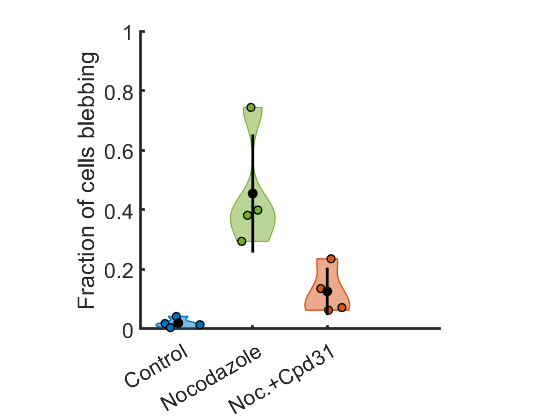

xticklabels({'Control', 'Nocodazole', 'Noc.+Cpd31'});
vpa.Box = 'off';
vpa.FontSize = 16;
vpa.XLim = [0.5,4.5];
vpa.YLim = [0,1];
vpa.YLabel.String = 'Fraction of cells blebbing';
vpa.LineWidth = 2;
axis(vpa, 'square');

### F7F: Rescue violin plots

CNTRL = table2array(BlebTable(strcmpi('CNTRL', BlebTable.Condition), "Rescue")); 
NCDZL = table2array(BlebTable(strcmpi('NCDZL', BlebTable.Condition), "Rescue"));
CPNOC = table2array(BlebTable(strcmpi('CPNOC', BlebTable.Condition), "Rescue"));
NRESC = table2array(BlebTable(strcmpi('NRESC', BlebTable.Condition), "Rescue"));
bRescue = table(CNTRL, NCDZL, CPNOC, NRESC);

figure; 
vpa = gca;
vB2 = violinplot(bRescue);

Fetch patch, scatter and line objects:

g = 1; p = 1; l = 1;
for c = 1:size(vpa.Children, 1)
    if strcmpi(vpa.Children(c).Type, 'Patch')
        patchObjects{p} = vpa.Children(c);
        p = p + 1;
    elseif strcmpi(vpa.Children(c).Type, 'Scatter')
        scatterGroup{g} = vpa.Children(c);
        g = g + 1;
    elseif strcmpi(vpa.Children(c).Type, 'Line')
        linesGroup{l} = vpa.Children(c);
        linesGroup{l}.Visible = 'on';
        l = l + 1;
    end
end

Color and label patches:

Tags = {'Noc. Rescue', 'Noc. + Cpd31', 'Nocodazole', 'Control'}; 
% Colors = { [0.85,0.33,0.10], [0.39,0.83,0.07], [0.00,0.45,0.74]}; % Blue Green Orange (in reverse order)
Colors = {[0.93, 0.69, 0.13], [0.85,0.33,0.10], [0.47,0.67,0.19], [0.00,0.45,0.74]}; % Blue Olive-Green Orange Gold (in reverse order)
t = 1;
for p = 2:2:8
    patchObjects{p}.Tag = ['Patch', Tags{t}]; 
    patchObjects{p}.FaceColor = Colors{t};
    patchObjects{p}.EdgeColor = patchObjects{p}.FaceColor;
    patchObjects{p}.FaceAlpha = 0.5;
    patchObjects{p}.LineWidth = 1;
    
    % Match the color of the mean line and hide it:
    linesGroup{p}.Color = Colors{t};
    linesGroup{p}.Visible = 0;
    
    t = t + 1;
end

Hide whiskers and error bar patches

for p = 1:2:7
    patchObjects{p}.EdgeColor = 'k';
    patchObjects{p}.FaceColor = 'k';
    patchObjects{p}.Visible = 'off';    
    
    linesGroup{p}.Visible = 'off'; % Hide whiskers
end

Color scatterplots:

c = 1;
for g = 4:4:16
    scatterGroup{g}.MarkerFaceColor = Colors{c};
    scatterGroup{g}.MarkerEdgeColor = 'k';
    scatterGroup{g}.LineWidth = 1;
    scatterGroup{g}.SizeData = 36;
    c = c + 1;       
end

c = 1;
for g = 3:4:15
    scatterGroup{g}.MarkerFaceColor = Colors{c};
    scatterGroup{g}.MarkerEdgeColor = 'k';
    scatterGroup{g}.LineWidth = 1.5;
    scatterGroup{g}.SizeData = 46;
    scatterGroup{g}.Visible = 'off';
    c = c + 1;          
end


Add standard deviation error bars and means:

summaryRescue = table2array(bRescue)';
for c = 1:4
    line([c,c], [mean(summaryRescue(c,:))+std(summaryRescue(c,:)),...
        mean(summaryRescue(c,:))-std(summaryRescue(c,:))], 'LineWidth', 2, 'Color', 'k', 'Parent', vpa);
    scatter(c, mean(summaryRescue(c,:)), 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'SizeData', 46, 'Parent', vpa);
end

Add trial connection dashed lines:

% for g = 4:-1:2
%     for i = 1:size(summaryTable, 2)
%         line([scatterGroup{g*4}.XData(i), scatterGroup{g*4-4}.XData(i)],...
%             [scatterGroup{g*4}.YData(i), scatterGroup{g*4-4}.YData(i)], 'LineStyle', ':', 'Color', 'k', 'Parent', vpa);        
%     end
% end

Add labels and adjust axes properties:

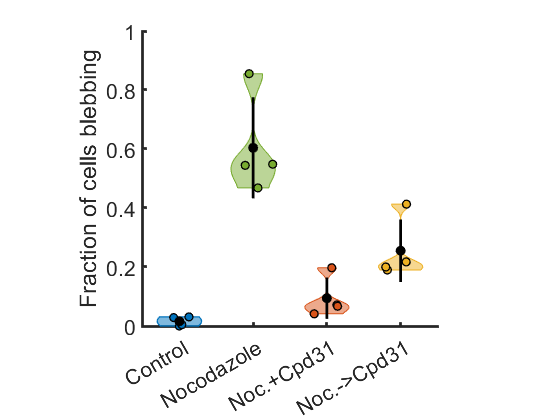

xticklabels({'Control', 'Nocodazole', 'Noc.+Cpd31', 'Noc.->Cpd31'});
vpa.Box = 'off';
vpa.FontSize = 16;
vpa.XLim = [0.5,4.5];
vpa.YLim = [0,1];
vpa.YLabel.String = 'Fraction of cells blebbing';
vpa.LineWidth = 2;
axis(vpa, 'square');

## F7J: Cell area at the last timepoint

⚠️ Make sure the script `plotAreaChangeNocCPD31.mlx` has been run so that `lastPointTable` can be loaded.

load('MainFigures\Fig7\Fig 7 F, H-J\Results\Fig 7J - Lat time point area\CellAreaNocRescueLastMeanPoint.mat', "lastPointTable");
CNTRL = table2array(lastPointTable(strcmpi('CNTRL', lastPointTable.Treatment), "LastMeanValue")); 
NCDZL = table2array(lastPointTable(strcmpi('NCDZL', lastPointTable.Treatment), "LastMeanValue"));
CPNOC = table2array(lastPointTable(strcmpi('CPNOC', lastPointTable.Treatment), "LastMeanValue"));
NRESC = table2array(lastPointTable(strcmpi('NRESC', lastPointTable.Treatment), "LastMeanValue"));
bRescueEndpoint = table(CNTRL, NCDZL, CPNOC, NRESC);

figure; 
vpa = gca;
vB2 = violinplot(bRescueEndpoint);

Fetch patch, scatter and line objects:

g = 1; p = 1; l = 1;
for c = 1:size(vpa.Children, 1)
    if strcmpi(vpa.Children(c).Type, 'Patch')
        patchObjects{p} = vpa.Children(c);
        p = p + 1;
    elseif strcmpi(vpa.Children(c).Type, 'Scatter')
        scatterGroup{g} = vpa.Children(c);
        g = g + 1;
    elseif strcmpi(vpa.Children(c).Type, 'Line')
        linesGroup{l} = vpa.Children(c);
        linesGroup{l}.Visible = 'on';
        l = l + 1;
    end
end

Color and label patches:

Tags = {'Noc. Rescue', 'Noc. + Cpd31', 'Nocodazole', 'Control'}; 
% Colors = { [0.85,0.33,0.10], [0.39,0.83,0.07], [0.00,0.45,0.74]}; % Blue Green Orange (in reverse order)
Colors = {[0.93, 0.69, 0.13], [0.85,0.33,0.10], [0.47,0.67,0.19], [0.00,0.45,0.74]}; % Blue Olive-Green Orange Gold (in reverse order)
t = 1;
for p = 2:2:8
    patchObjects{p}.Tag = ['Patch', Tags{t}]; 
    patchObjects{p}.FaceColor = Colors{t};
    patchObjects{p}.EdgeColor = patchObjects{p}.FaceColor;
    patchObjects{p}.FaceAlpha = 0.5;
    patchObjects{p}.LineWidth = 1;
    
    % Match the color of the mean line and hide it:
    linesGroup{p}.Color = Colors{t};
    linesGroup{p}.Visible = 0;
    
    t = t + 1;
end

Hide whiskers and error bar patches

for p = 1:2:7
    patchObjects{p}.EdgeColor = 'k';
    patchObjects{p}.FaceColor = 'k';
    patchObjects{p}.Visible = 'off';    
    
    linesGroup{p}.Visible = 'off'; % Hide whiskers
end

Color scatterplots:

c = 1;
for g = 4:4:16
    scatterGroup{g}.MarkerFaceColor = Colors{c};
    scatterGroup{g}.MarkerEdgeColor = 'k';
    scatterGroup{g}.LineWidth = 1;
    scatterGroup{g}.SizeData = 36;
    c = c + 1;       
end

c = 1;
for g = 3:4:15
    scatterGroup{g}.MarkerFaceColor = Colors{c};
    scatterGroup{g}.MarkerEdgeColor = 'k';
    scatterGroup{g}.LineWidth = 1.5;
    scatterGroup{g}.SizeData = 46;
    scatterGroup{g}.Visible = 'off';
    c = c + 1;          
end


Add standard deviation error bars and means:

summaryRescue = table2array(bRescueEndpoint)';
for c = 1:4
    line([c,c], [mean(summaryRescue(c,:))+std(summaryRescue(c,:)),...
        mean(summaryRescue(c,:))-std(summaryRescue(c,:))], 'LineWidth', 2, 'Color', 'k', 'Parent', vpa);
    scatter(c, mean(summaryRescue(c,:)), 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'SizeData', 46, 'Parent', vpa);
end

Add trial connection dashed lines:

% for g = 4:-1:2
%     for i = 1:size(summaryTable, 2)
%         line([scatterGroup{g*4}.XData(i), scatterGroup{g*4-4}.XData(i)],...
%             [scatterGroup{g*4}.YData(i), scatterGroup{g*4-4}.YData(i)], 'LineStyle', ':', 'Color', 'k', 'Parent', vpa);        
%     end
% end

Add labels and adjust axes properties:

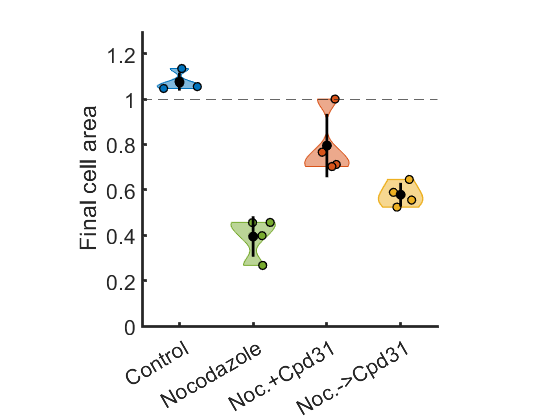

xticklabels({'Control', 'Nocodazole', 'Noc.+Cpd31', 'Noc.->Cpd31'});
vpa.Box = 'off';
vpa.FontSize = 16;
vpa.XLim = [0.5,4.5];
vpa.YLim = [0,1.3];
vpa.YLabel.String = 'Final cell area';
vpa.LineWidth = 2;
yline(1, '--');
axis(vpa, 'square');

 [~,index1] = sortrows([retainedObjectsData.Area].', direction); 
    biggestObjectsList = retainedObjectsList(index1(end:-1:end-topSize-1)); 
    biggestObjectsData = retainedObjectsData(index1(end:-1:end-topSize-1)); clear index1
% 
% show_smallest = true;
% if show_smallest
%     [~,index1] = sortrows([retainedObjectsData.Area].'); 
%     smallestObjectsList = retainedObjectsList(index1(1:topSize)); 
%     smallestObjectsData = retainedObjectsData(index1(1:topSize)); clear index1
% end
% 
% show_eccentric = true;
% if show_eccentric
%     [~,index1] = sortrows([retainedObjectsData.Eccentricity].'); 
%     eccentricObjectsList = retainedObjectsList(index1(end:-1:end-topSize)); 
%     eccentricObjectsData = retainedObjectsData(index1(end:-1:end-topSize)); clear index1
% end
% 
% show_solid = true;
% if show_solid
%     [~,index1] = sortrows([retainedObjectsData.Solidity].'); 
%     solidObjectsList = retainedObjectsList(index1(end:-1:end-topSize)); 
%     solidObjectsData = retainedObjectsData(index1(end:-1:end-topSize)); clear index1
% end
% 
% show_long = true;
% if show_long
%     [~,index1] = sortrows([retainedObjectsData.MajorAxis].'); 
%     longObjectsList = retainedObjectsList(index1(end:-1:end-topSize)); 
%     longObjectsData = retainedObjectsData(index1(end:-1:end-topSize)); clear index1
% end
% 
% show_intense = true;
% if show_intense
%     [~,index1] = sortrows([retainedObjectsData.MeanIntensity].'); 
%     intenseObjectsList = retainedObjectsList(index1(end:-1:end-topSize)); 
%     intenseObjectsData = retainedObjectsData(index1(end:-1:end-topSize)); clear index1    
% end
% 
% show_ruffled = true;
% if show_ruffled
%     [~,index1] = sortrows([retainedObjectsData.PerSqrdOverArea].'); 
%     ruffledObjectsList = retainedObjectsList(index1(end:-1:end-topSize)); 
%     ruffledObjectsData = retainedObjectsData(index1(end:-1:end-topSize)); clear index1    
% end

## F7G siRNA + Blebbing Experiments

load("siBlebbingFractionsArray.mat");

siBlebTable = array2table(siBlebArray);
siBlebTable.Properties.VariableNames = {'Control siNT', 'Control siSLK/LOK', 'Nocodazole siNT', 'Nocodazole siSLK/LOK'};
siBlebTable.Properties.RowNames = {'240326-Nada', '240328-Seph', '240330-Seph', '240507-Seph', '240510-Arnold'};

save("Z:\Rho paper data\Final Data\Violin Plots and Spreadsheets\siRNA Blebbing Data\siBlebbingFractionsTable.mat","siBlebTable");

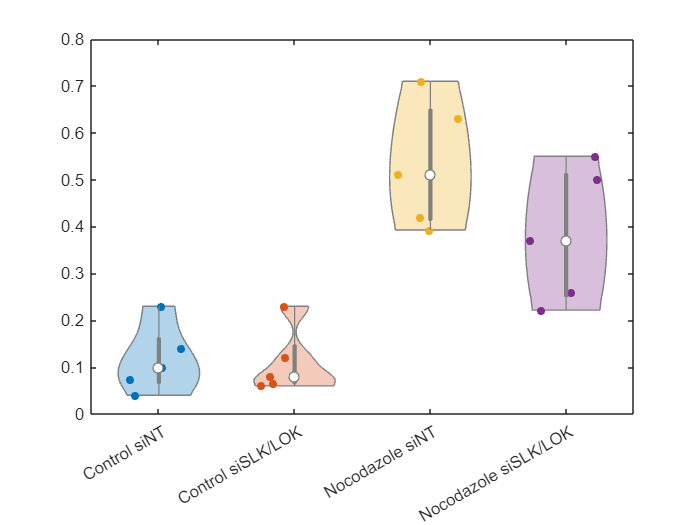

fg = figure; vSB = gca;
vpSB = violinplot(siBlebTable);

Fetch patch, scatter and line objects:

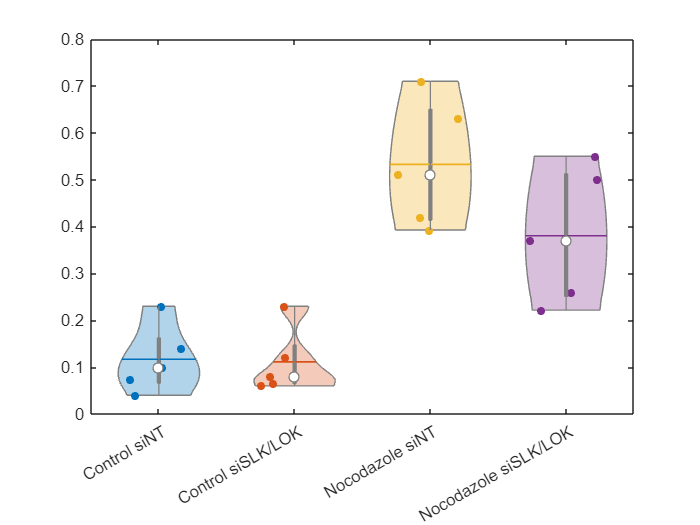

g = 1; p = 1; l = 1;
for c = 1:size(vSB.Children, 1)
    if strcmpi(vSB.Children(c).Type, 'Patch')
        patchObjects{p} = vSB.Children(c);
        p = p + 1;
    elseif strcmpi(vSB.Children(c).Type, 'Scatter')
        scatterGroup{g} = vSB.Children(c);
        g = g + 1;
    elseif strcmpi(vSB.Children(c).Type, 'Line')
        linesGroup{l} = vSB.Children(c);
        linesGroup{l}.Visible = 'on';
        l = l + 1;
    end
end

Color and label patches:

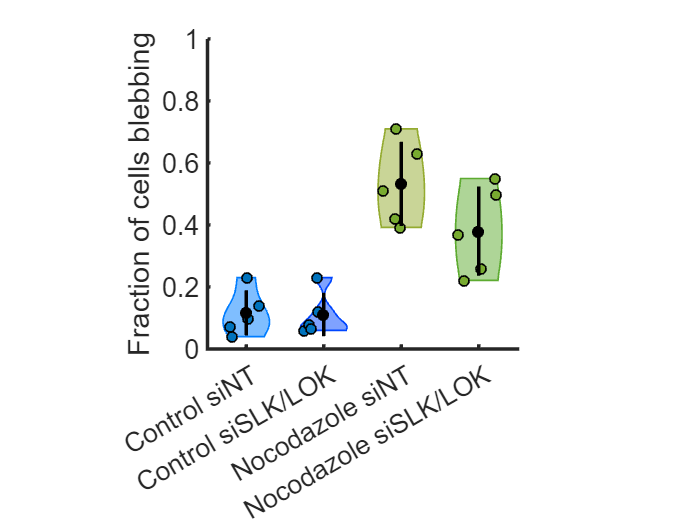

Tags = {'Noc. Rescue', 'Noc. + Cpd31', 'Nocodazole', 'Control'}; 
% Colors = { [0.85,0.33,0.10], [0.39,0.83,0.07], [0.00,0.45,0.74]}; % Blue Green Orange (in reverse order)
% Colors = {[0.93, 0.69, 0.13], [0.85,0.33,0.10], [0.47,0.67,0.19], [0.00,0.45,0.74]}; % Blue Olive-Green Orange Gold (in reverse order)
% Colors = {[0.47,0.67,0.19], [0.47,0.67,0.19], [0.00,0.45,0.74], [0.00,0.45,0.74]}; % Blue Blue Green Green (in reverse order)
Colors = {[93,171,48]/255, [148,171,48]/255, [0,70,255]/255, [0,125,255]/255};
t = 1;
for p = 2:2:8
    patchObjects{p}.Tag = ['Patch', Tags{t}]; 
    patchObjects{p}.FaceColor = Colors{t};
    patchObjects{p}.EdgeColor = patchObjects{p}.FaceColor;
    patchObjects{p}.FaceAlpha = 0.5;
    patchObjects{p}.LineWidth = 1;
    
    % Match the color of the mean line and hide it:
    linesGroup{p}.Color = Colors{t};
    linesGroup{p}.Visible = 0;
    
    t = t + 1;
end

Hide whiskers and error bar patches

for p = 1:2:7
    patchObjects{p}.EdgeColor = 'k';
    patchObjects{p}.FaceColor = 'k';
    patchObjects{p}.Visible = 'off';    
    
    linesGroup{p}.Visible = 'off'; % Hide whiskers
end

Color scatterplots:

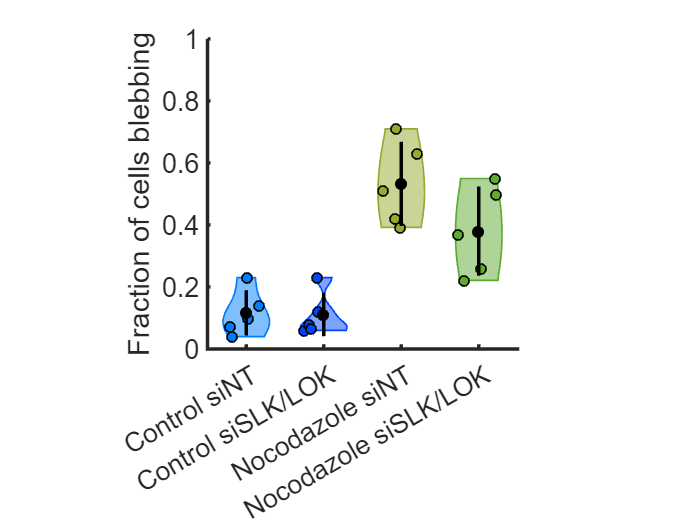

c = 1;
for g = 4:4:16
    scatterGroup{g}.MarkerFaceColor = Colors{c};
    scatterGroup{g}.MarkerEdgeColor = 'k';
    scatterGroup{g}.LineWidth = 1;
    scatterGroup{g}.SizeData = 36;
    c = c + 1;       
end

c = 1;
for g = 3:4:15
    scatterGroup{g}.MarkerFaceColor = Colors{c};
    scatterGroup{g}.MarkerEdgeColor = 'k';
    scatterGroup{g}.LineWidth = 1.5;
    scatterGroup{g}.SizeData = 46;
    scatterGroup{g}.Visible = 'off';
    c = c + 1;          
end

Add standard deviation error bars and means:

summaryBlebSiRNA = table2array(siBlebTable)';
for c = 1:4
    line([c,c], [mean(summaryBlebSiRNA(c,:))+std(summaryBlebSiRNA(c,:)),...
        mean(summaryBlebSiRNA(c,:))-std(summaryBlebSiRNA(c,:))], 'LineWidth', 2, 'Color', 'k', 'Parent', vSB);
    scatter(c, mean(summaryBlebSiRNA(c,:)), 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'SizeData', 46, 'Parent', vSB);
end

Add trial connection dashed lines:

% for g = 4:-1:2
%     for i = 1:size(summaryTable, 2)
%         line([scatterGroup{g*4}.XData(i), scatterGroup{g*4-4}.XData(i)],...
%             [scatterGroup{g*4}.YData(i), scatterGroup{g*4-4}.YData(i)], 'LineStyle', ':', 'Color', 'k', 'Parent', vSB);        
%     end
% end

Add labels and adjust axes properties:

Trying to add two-line x tick labels (but failing so far)

% % Get tick positions
% yTicks = get(gca, 'ytick');
% xTicks = get(gca, 'xtick');
% % Reset XTicklabels onto multiple lines (2nd line being twice of first)
% minY = min(yTicks);
% VerticalOffset = 0.6;
% HorizontalOffset = 0.2;
% for xx = 1:length(xTicks)
%     text(xTicks(xx) - HorizontalOffset, minY - VerticalOffset, ...
%         ['$$\begin{array}{c}', num2str(xTicks(xx)), '\\', num2str(2 * xTicks(xx)), '\end{array}$$'], ...
%         'Interpreter', 'latex');
% end

vSB.Box = 'off';
vSB.FontSize = 16;
vSB.XLim = [0.5,4.5];
vSB.YLim = [0,1];
vSB.YLabel.String = 'Fraction of cells blebbing';
vSB.LineWidth = 2;

axis(vSB, 'square');
savefig(fg, "Z:\Rho paper data\Final Data\Violin Plots and Spreadsheets\siRNA Blebbing Data\siRNA Blebbing Violinplot.fig");
exportgraphics(fg, "Z:\Rho paper data\Final Data\Violin Plots and Spreadsheets\siRNA Blebbing Data\siRNA Blebbing Violinplot.png");